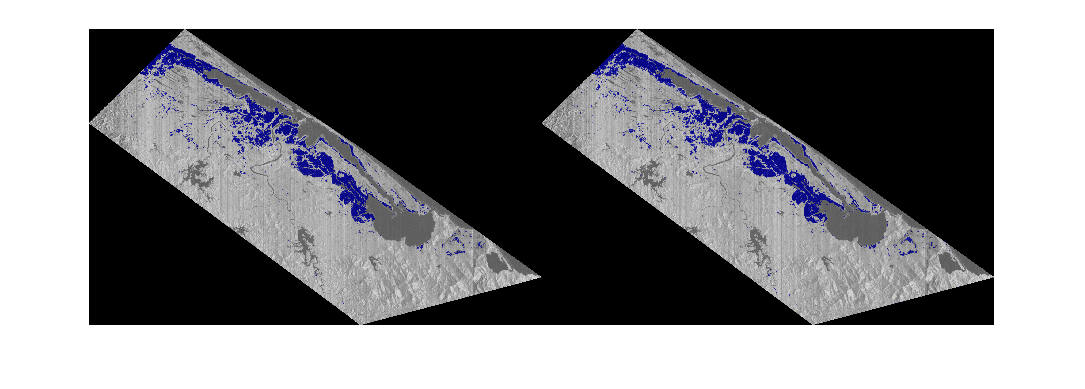

load('results\twobands_trainedNetwork_2020_12_02__15_49_44.mat');
predictPatchSize = [1024 1024];
test_input = imread(fullfile(pwd, dataFolder, 'test', 'images','input_hue_2910.tif'));
input = custominputreader(test_input);
nor_input = normalize(test_input(:,:,1), 'range', [0 1]);

test_label = imread(fullfile(pwd, dataFolder, 'test', 'labels','label_hue_2910.tif'));
l1 = double(test_label + 1);
b1 = labeloverlay(nor_input,l1,'ColorMap', [0.7 0.7 0.7; 0 0 1]);

output = segmentImage(input,trainedNetwork_1,predictPatchSize);
l2 = double(output);
b2 = labeloverlay(nor_input,l2,'ColorMap', [0.7 0.7 0.7; 0 0 1]);
imshow(cat(2,b1, b2));

unique(output)

ans = 2×1 uint8 column vector
   1
   2


lab  = categorical(test_label, [0 1], {'no_label' 'flood'});
pred = categorical(output, [1 2], {'no_label' 'flood'});
categories(pred)

ans = 2×1 cell array
    {'no_label'}
    {'flood'   }


[countpred, heading] = summary(ordinal(pred));
heading

heading = 2×1 cell array
    {'no_label'}
    {'flood'   }


sum(sum(countpred()))

ans = 8566173

sum(countpred(1,:))

ans = 8238166

sum(countpred(2,:))

ans = 328007

dataFolder = '/GEE_30m';
labelIDs = [0 1];
pixelLabelIDs = {0 1};
classes = ["no_label", "flood"];

testImgDir = fullfile(pwd, dataFolder, '/test', 'images');
testLabelDir = fullfile(pwd, dataFolder, '/test', 'labels');

testImds = imageDatastore(testImgDir, 'readfcn', @(filename) custominputreader(imread(filename)));
testPxds = pixelLabelDatastore(testLabelDir, classes, pixelLabelIDs);

result = semanticseg(testImds, trainedNetwork_1,'WriteLocation', 'trash');

Running semantic segmentation network
-------------------------------------
* Processed 1 images.

Error using DAGNetwork/activations (line 245)
Out of memory.

Error in semanticseg>iClassifyImagePixels (line 498)
    allScores = activations(net, X, layerName, ...

Error in 